## Materials classification - A1

### Import dataset

clear all;
clc;

% Consider 2 images from a sample directory
% inputDir = ".\\Data\\"
fabricImgFile = ".\\Data\\image\\fabric\\fabric_moderate_001_new.jpg";
foliageImgFile = ".\\Data\\image\\foliage\\foliage_final_001_new.jpg";
glassImgFile = ".\\Data\\image\\glass\\glass_moderate_001_new.jpg";
leatherImgFile = ".\\Data\\image\\leather\\leather_moderate_001_new.jpg";
metalImgFile = ".\\Data\\image\\metal\\metal_moderate_001_new.jpg";
paperImgFile = ".\\Data\\image\\paper\\paper_moderate_001_new.jpg";
plasticImgFile = ".\\Data\\image\\plastic\\plastic_moderate_001_new.jpg";
stoneImgFile = ".\\Data\\image\\stone\\stone_moderate_001_new.jpg";
waterImgFile = ".\\Data\\image\\water\\water_moderate_001_new.jpg";
woodImgFile = ".\\Data\\image\\wood\\wood_moderate_001_new.jpg";

fabricImgFile = imread(fabricImgFile);
foliageImgFile = imread(foliageImgFile);
glassImgFile = imread(glassImgFile);
leatherImgFile = imread(leatherImgFile);
metalImgFile = imread(metalImgFile);
paperImgFile = imread(paperImgFile);
plasticImgFile = imread(plasticImgFile);
stoneImgFile = imread(stoneImgFile);
waterImgFile = imread(waterImgFile);
woodImgFile = imread(woodImgFile);

testImgSet = {fabricImgFile, foliageImgFile, glassImgFile, leatherImgFile, ...
    metalImgFile, paperImgFile, plasticImgFile, stoneImgFile, waterImgFile, woodImgFile};

### Feature extraction

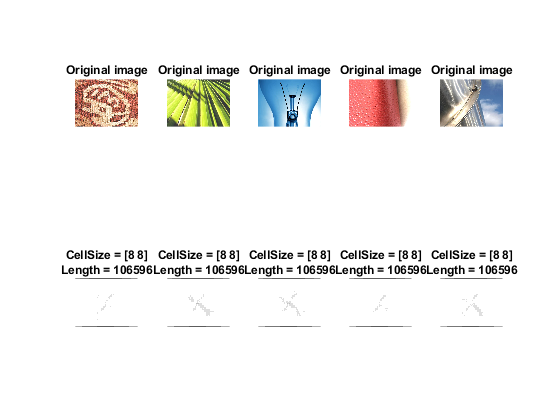

% HOG features extraction and visualization
plotIdx = 1;
for idx = 1:5
    [hog_8x8, vis8x8] = extractHOGFeatures(testImgSet{idx},'CellSize',[8 8]);
    % Visualize the HOG features
    subplot(2,5,plotIdx);
    imshow(testImgSet{idx});
    title('Original image');
    subplot(2,5,plotIdx+5);
    plot(vis8x8);
    title({'CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});
    plotIdx = plotIdx + 1;
end

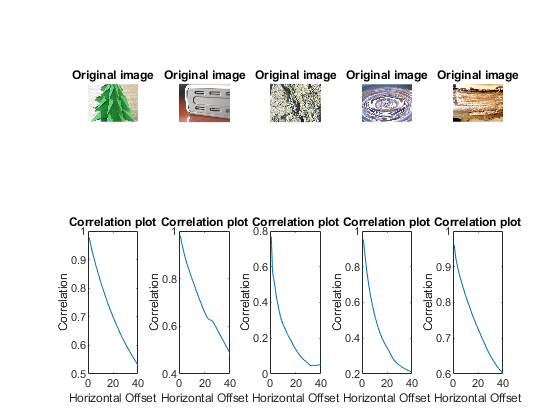

% GLCM correlation
plotIdx = 1;
offsets0 = [zeros(40,1) (1:40)'];
for idx = 6:10
    glcm = graycomatrix(rgb2gray(testImgSet{idx}), 'Offset', offsets0);
    stats = graycoprops(glcm,'Contrast Correlation');
    % Visualize the correlation
    subplot(2,5,plotIdx);
    imshow(testImgSet{idx});
    title('Original image');
    subplot(2,5,plotIdx+5);
    plot([stats.Correlation]);
    xlabel('Horizontal Offset')
    ylabel('Correlation')
    title('Correlation plot');
    plotIdx = plotIdx + 1;
end

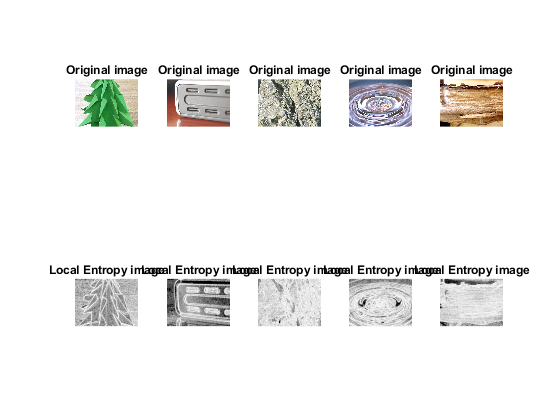

% Local Entropy measure
plotIdx = 1;
for idx = 6:10
    entropyImg = entropyfilt(rgb2gray(testImgSet{idx}));
    % Visualize the HOG features
    subplot(2,5,plotIdx);
    imshow(testImgSet{idx});
    title('Original image');
    subplot(2,5,plotIdx+5);
    imshow(entropyImg, []);
    title('Local Entropy image');
    plotIdx = plotIdx + 1;
end